Name: Yusu (Cosmo) Zhao

Student Number: 20761282

PartA:

1. I will define the taskspace as a subset of $E^3$. More specifically, I would say the task space is in the cuboid defined by the graph below (of size 0.8 x 0.8 x 1.6, x from 0.3 to 1.1, y from -0.8 to 0.8 and z from -0.1 to 0.7). In the task, we do not care about how to hit the ball and the trajectory after we hit it, so the angle is not quite imporatant here. The only thing we care about is the position of the ball inside the cuboid. The ball can be positioned at any point inside the cuboid. However, the ball will still have six degree of freedoms, as it can move to any position in the space with any orientation. In other words, it is a free body in the space.

                        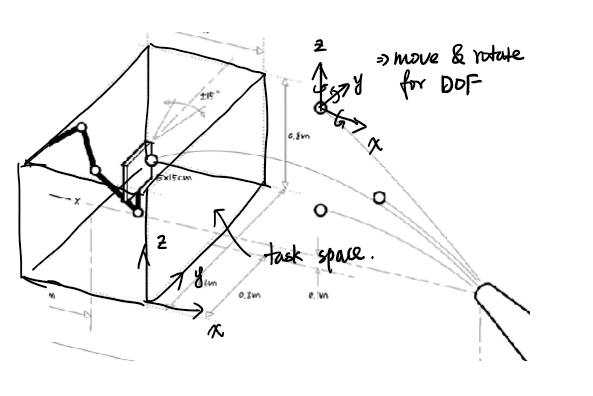

2. I will define the workspace as a subset of $E^3 \times S^1$because our paddle can move in the three directions (x, y, and z) in the space to catch the ball (even though it is restricted to the cuboid space, the paddle still need to move to any point of the space). And the paddle can also rotate in one direction. Therefore, the required DOF of the paddle is 4. 

                            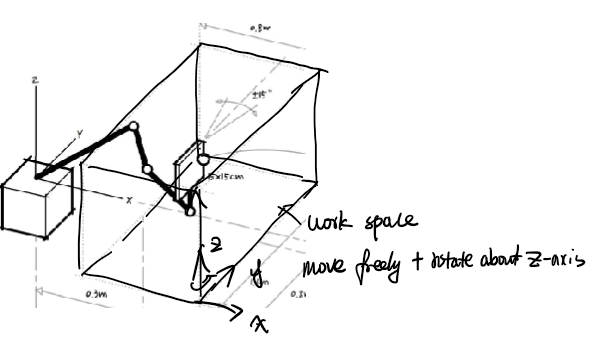

PartB:

1. To solve this problem, I used the formula for movement $p=p_0 +v_0 t+\frac{1}{2}at^2$ in each direction x, y and z. The requirement specifies two end point: either the ball finished passing through the cuboid or after it passed z=-0.1 if it did not hit the cuboid. Since the bottom border of the cuboid is also z=-0.1, I decided to stop when the ball passing through z=-0.1 and heading down as the end point anyway to simplify the code. Since we only have gravity as the acceleration, the trajectory is guaranteed to be a parabola, and there could be up to two points that the ball hit z=-0.1. I decided to take the one with larger time to ensure that the code can handle multiple cases including passing z=-0.1 twice. 

Since the movement of the ball in the z-direction can be easily defined by the movement formula above, I will solve the equation $-1=p_0 +v_0 t+\frac{1}{2}at^2$ with the quadratic formula, and take the larger solution as the end time. Then, I will create an array of time slices, and track the position of balls with the same formula and vector calculation. Finally, I will exploit the feature of matlab to check if the ball is in range. The condition is to check if the ball's coordinates sits inside the cuboid.

% Fill in the function template below to satisfy the problem outline above
function [p_ball, t_ball, in_range] = ball_trajectory(v0, ts)
% Inputs:
% v0 = [vx; vy; vz] - initial velocity measured in fixed frame
% ts - the sampling rate (time step) in seconds

% Constants:
% g = [gx; gy; gz] - acceleration due to gravity
% p0 = [x0; y0; z0] - initial ball position relative to the fixed frame
% t0 = start time in seconds
g = [0;0;-9.81];
p0 = [3;0;0];
t0 = 0;

% Generate the position array p_ball, the time vector t_ball, and the logical vector in_range

% Solve the quadratic function to predicate the end time
T = (-v0(3) - sqrt(v0(3)^2 - 2*g(3)*(p0(3)+0.1))) / g(3);
% Create time sampling vector
t_ball = 0:ts:T+ts;
% Use the movement formula to calculate the position of the ball at each time
p_ball = p0 + v0 * t_ball + g * (t_ball.^2) / 2;
% Check if the ball is inside the cuboid
in_range = p_ball(1,:) >= 0.3 & p_ball(1,:) <= 1.1 & p_ball(2,:) >= -0.8 & p_ball(2,:) <= 0.8 & p_ball(3,:) >= -0.1 & p_ball(3,:) <= 0.7;
% Convert the boolean result obtained above to double to match the requirement 
in_range = double(in_range);

end

With the trajectory of the balls and the in_range indicator, we can identify at what time the ball will hit the cuboid and where it will hit. Therefore, in the future, we can adjust our paddle to the postion accordingly. There could be many choices for us. For example, we can get several possible points from the trajectory that is inside the cuboid by the in_range and p_ball vectors, and then pick one value. Then, we pass the value to some other functions developed in the future as the point we want our paddle to catch the ball. 

Besides, we might also want to consider about the dynamics of our robot in the future, so the t_ball vector can also be useful in the future to calculate the velocity of the paddle.

2. 

To calculate p_hb, I use the subscript substitution rule: ${\left\lbrack p_{\textrm{hb}}^{\top \;} \;1\right\rbrack }^{\top \;} =T_{\textrm{hs}} {\left\lbrack p_{\textrm{sb}}^{\top \;} \;\;1\right\rbrack }^{\top } ={\left(T_{\textrm{sh}} \right)}^{-1} {\left\lbrack p_{\textrm{sb}}^{\top \;} \;\;1\right\rbrack }^{\top }$

To calculate the transformation matrix of the pose, we need to first find the rotation matrix and the translation relative to the s frame, then combine them together to get the translation matrix $T_{\textrm{hc}}$, then we obtain the trasform matrix of c relative to s frame by$T_{\textrm{sc}} =T_{\textrm{sh}} T_{\textrm{hc}}$

We first caculate $\hat{\omega \;} \theta \;\;$which defines the rotation axis and angle. In this case, we should rotate about the y-axis of the h frame with angle theta. Then we calculate the skew matrix $\left\lbrack \hat{\;\omega \;} \theta \;\right\rbrack$and use it to calculate the rotation matrix $\textrm{Rot}\left(\hat{\;\omega } \theta \;\right)=R_{\textrm{hc}}$.

For the translation, since we need to be 0.01m away from the ball, I subtract 0.01 from the distance. The following graph shows how it works. The vector $p_{\textrm{norm}}$ represents the norm vector of the paddle, from c to the center of the ball in h frame. When there is no rotation, $p_{\textrm{norm}}$ aligns with the z-axis of the h frame. When there is a rotation, the $p_{\textrm{norm}}$ vector will be rotated as well by the rotation matrix. After the rotation, we can subtract the vector from $p_{\textrm{hb}}$ to get the vector $p_{\textrm{hc}}$.

                                                                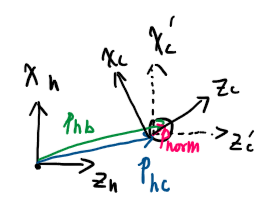

With $R_{\textrm{hc}}$ and $p_{\textrm{hc}}$, we will be able to construct $T_{\textrm{hc}}$ Then we use $T_{\textrm{sc}} =T_{\textrm{sh}} T_{\textrm{hc}}$

Finally, to get the transformation from home pose to the contact pose, we only need to get $T_{\textrm{hc}} =T_{\textrm{hs}} T_{\textrm{sc}} ={\left(T_{\textrm{sh}} \right)}^{-1} T_{\textrm{sc}}$

% Fill in the function template below to satisfy the problem outline above

function [p_hb, T_sc, T_hc] = make_contact(p_sb, theta)
% Inputs:
% p_sb - fixed ball position (relative to the fixed frame)
% theta - desired paddle contact angle about a vertical axis

% Constants:
% T_sh - home pose of the paddle (relative to the fixed frame)
R_sh = [0 0 1; 1 0 0; 0 1 0];
p_sh = [0.25; 0; 0.25];
T_sh = RpToTrans(R_sh, p_sh);

% Generate:
% p_hb - the position of the ball (relative to the home pose),
% T_sc - the contact pose (relative to the fixed frame), and
% T_hc - the motion required to move from the home pose to the contact pose.

p_hb = TransInv(T_sh) * [p_sb; 1];
p_hb = p_hb(1:3);
omg = [0; 1; 0] * theta; % Rotation about the z-axis by theta
so3mat = VecToso3(omg);  % Calculate the skew
R_hc = MatrixExp3(so3mat); % Calculate the exponential
offset = (R_hc * [0;0;1]) * 0.01;
p_hc = p_hb - offset; % 0.01m away from the ball
T_sc = T_sh * RpToTrans(R_hc, p_hc);
T_hc = TransInv(T_sh) * T_sc;

end

With the funciton, we can now easily calculate how should we move the paddle in it's original frame. Since the function take into the position of the ball and an angle, we can combine this function with the previous one in question 1 to calculate the position of the paddle to catch the ball. 

Besides, we might need to do the inverse dynamics in the future to calculate the join positions with the p_hb vector and the T_hb transformation. The T_hc transformation can also be useful if we want to consider some other forces expressed in the frame s. The ball trajectory is also expressed in s frame so the transformation can be useful in this case as well. 